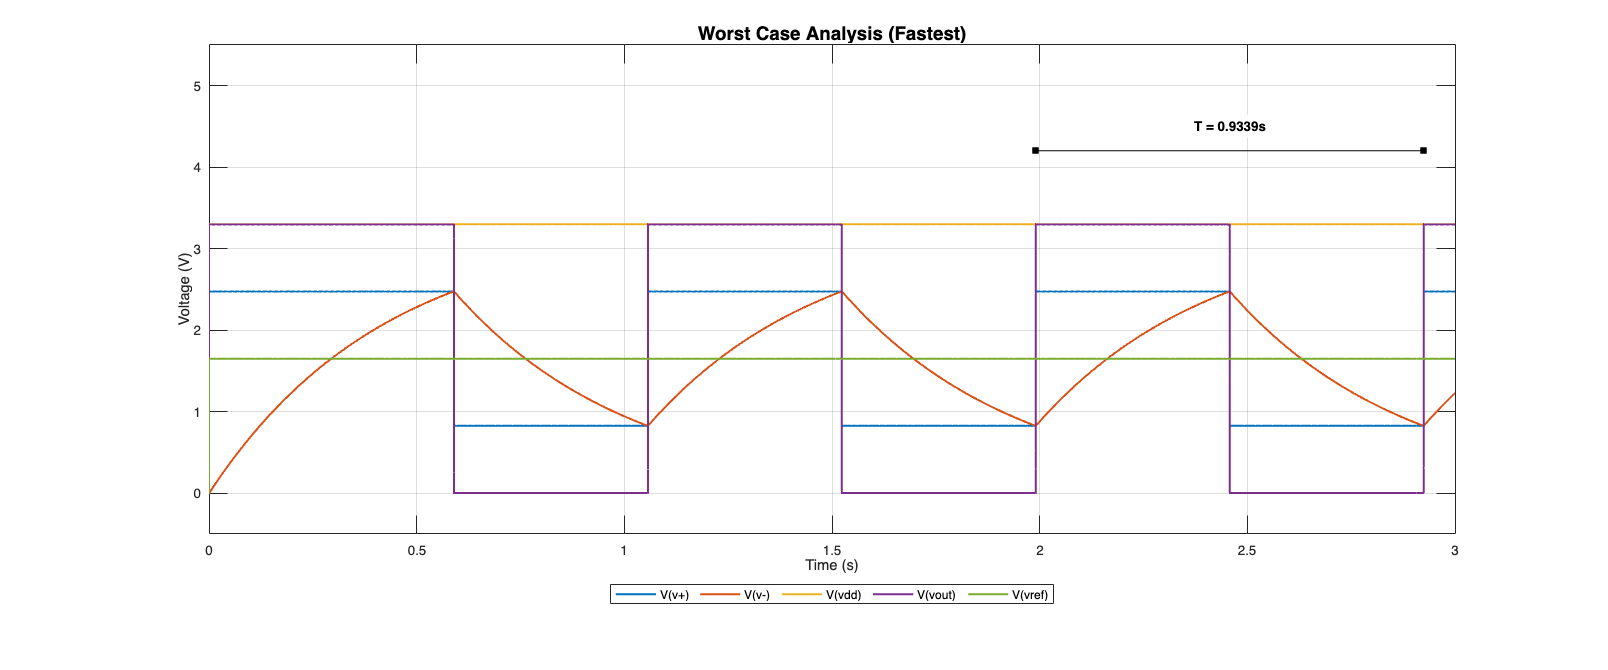

% --- 1. ROBUST IMPORT ---
filename = 'wc_data.txt';
fid = fopen(filename, 'r');
if fid == -1, error('File not found!'); end
raw_cell = textscan(fid, '%s', 'Delimiter', '\n'); 
fclose(fid);
clean_lines = raw_cell{1}(~cellfun('isempty', regexp(raw_cell{1}, '^[0-9\+\-\.]')));
data = str2double(split(clean_lines));

% --- 2. DATA PROCESSING ---
t = data(:,1);
signals = data(:, 2:end); 
col_vout = 4; 
sig_names = {'V(v+)', 'V(v-)', 'V(vdd)', 'V(vout)', 'V(vref)'};
colors = [0 0.447 0.741; 0.85 0.325 0.098; 0.929 0.694 0.125; 0.494 0.184 0.556; 0.466 0.674 0.188];

run_starts = [1; find(diff(t) < 0) + 1];
run_ends = [run_starts(2:end) - 1; length(t)];
num_runs = length(run_starts);

% Helper: Find Period
function [T, t1, t2] = get_steady_period(t_vec, v_vec)
    rising_edges = find(diff(v_vec > 2.5) == 1);
    if length(rising_edges) >= 3
        idx1 = rising_edges(end-1); idx2 = rising_edges(end);
        t1 = t_vec(idx1); t2 = t_vec(idx2); T = t2 - t1;
    elseif length(rising_edges) == 2
        idx1 = rising_edges(1); idx2 = rising_edges(2);
        t1 = t_vec(idx1); t2 = t_vec(idx2); T = t2 - t1;
    else
        T = NaN; t1=0; t2=0;
    end
end

% --- FIGURE 1: FASTEST CASE ---
% Position: [Left Bottom Width Height] -> 1200x500 makes it wide
figure('Name', 'Fastest Case', 'Color', 'w', 'Position', [100 100 1200 500]);
idx_s = run_starts(1); 
idx_e = run_ends(1);
t_run = t(idx_s:idx_e);
sig_run = signals(idx_s:idx_e, :);
[T_fast, t1, t2] = get_steady_period(t_run, sig_run(:,col_vout));

hold on; box on; grid on;
for k = 1:5
    plot(t_run, sig_run(:,k), 'LineWidth', 1.5, 'Color', colors(k,:), 'DisplayName', sig_names{k});
end

% Annotation
if ~isnan(T_fast)
    y_mark = 4.2; % Moved up slightly
    plot([t1 t2], [y_mark y_mark], 'k-s', 'MarkerFaceColor','k', 'HandleVisibility','off');
    text((t1+t2)/2, y_mark+0.3, sprintf('T = %.4fs', T_fast), ...
        'HorizontalAlignment','center', 'FontWeight','bold', 'BackgroundColor', 'w');
end

title('Worst Case Analysis (Fastest)', 'FontSize', 14);
xlabel('Time (s)'); ylabel('Voltage (V)');
legend('Location', 'bestoutside', 'Orientation', 'horizontal'); % Legend at bottom/side
xlim([0 max(t_run)]);
ylim([-0.5 5.5]); % Forced limits to keep text visible

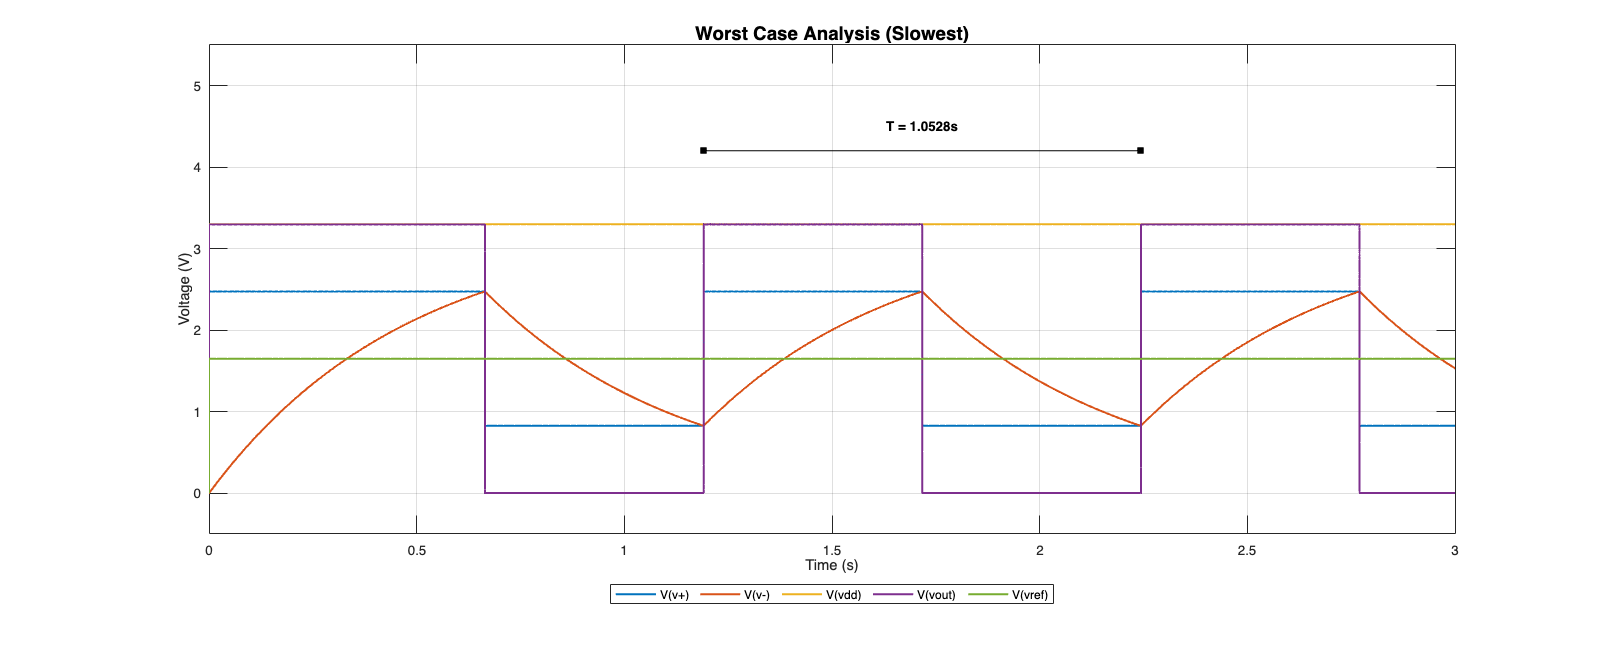


% --- FIGURE 2: SLOWEST CASE ---
figure('Name', 'Slowest Case', 'Color', 'w', 'Position', [100 100 1200 500]);
idx_s = run_starts(end); 
idx_e = run_ends(end);
t_run = t(idx_s:idx_e);
sig_run = signals(idx_s:idx_e, :);
[T_slow, t1, t2] = get_steady_period(t_run, sig_run(:,col_vout));

hold on; box on; grid on;
for k = 1:5
    plot(t_run, sig_run(:,k), 'LineWidth', 1.5, 'Color', colors(k,:), 'DisplayName', sig_names{k});
end

if ~isnan(T_slow)
    y_mark = 4.2;
    plot([t1 t2], [y_mark y_mark], 'k-s', 'MarkerFaceColor','k', 'HandleVisibility','off');
    text((t1+t2)/2, y_mark+0.3, sprintf('T = %.4fs', T_slow), ...
        'HorizontalAlignment','center', 'FontWeight','bold', 'BackgroundColor', 'w');
end

title('Worst Case Analysis (Slowest)', 'FontSize', 14);
xlabel('Time (s)'); ylabel('Voltage (V)');
legend('Location', 'bestoutside', 'Orientation', 'horizontal');
xlim([0 max(t_run)]);
ylim([-0.5 5.5]);

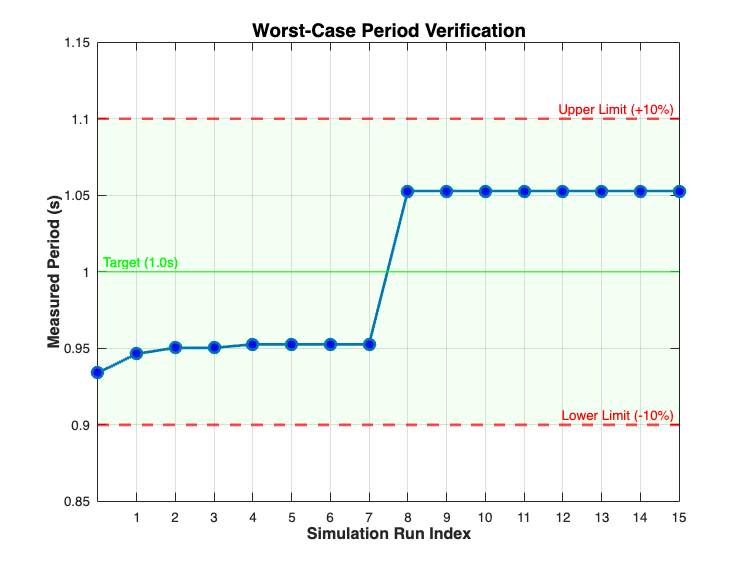

% 1. Load the Data
data = readtable('wc_periods.txt'); 

% --- THE FIX: Access data by Column Number, not Name ---
% This works regardless of whether it's named 'step', 'Step', 'Var1', etc.
x = data{:, 1};  % The Step Number (1st Column)
y = data{:, 2};  % The Period (2nd Column)

% 2. Setup the Plot
figure('Color', 'w');
hold on; grid on; box on;

% 3. Plot the Periods
plot(x, y, 'o-', ...
    'LineWidth', 2, ...
    'MarkerSize', 8, ...
    'MarkerFaceColor', 'b', ...
    'Color', [0 0.447 0.741]); 

% 4. Add the "Goal Posts"
yline(1.1, 'r--', 'Upper Limit (+10%)', 'LineWidth', 2, 'LabelHorizontalAlignment', 'right');
yline(0.9, 'r--', 'Lower Limit (-10%)', 'LineWidth', 2, 'LabelHorizontalAlignment', 'right');
yline(1.0, 'g-', 'Target (1.0s)', 'LineWidth', 1, 'LabelHorizontalAlignment', 'left');

% 5. Add "Safety Zones" (Green shading)
fill([min(x) max(x) max(x) min(x)], ...
     [0.9 0.9 1.1 1.1], 'g', 'FaceAlpha', 0.05, 'EdgeColor', 'none');

% 6. Labels
title('Worst-Case Period Verification', 'FontSize', 14);
xlabel('Simulation Run Index', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Measured Period (s)', 'FontSize', 12, 'FontWeight', 'bold');
ylim([0.85 1.15]); 
xticks(1:length(x)); 

hold off;

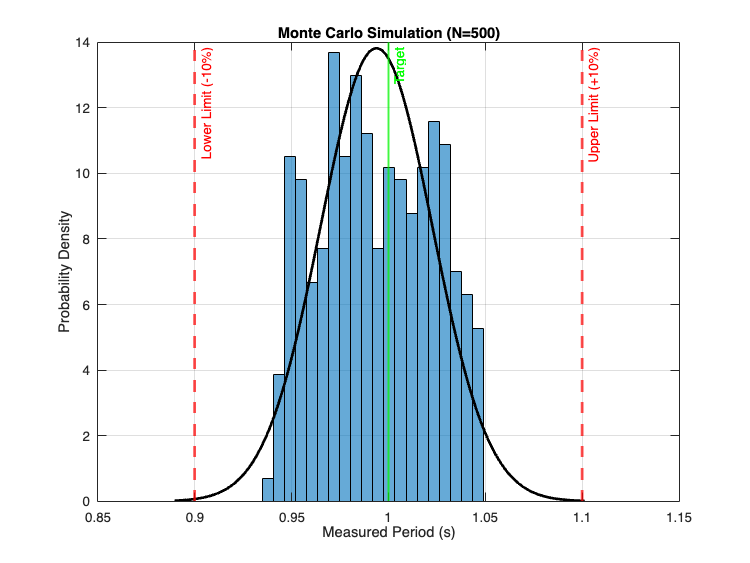

% 1. Load the data
data = readtable('sim/montecarlo/montecarlo_MP1.txt', 'Delimiter', '\t');

% --- DEBUGGING TIP ---
% If you ever get this error again, uncomment the line below to see the actual names:
% disp(data.Properties.VariableNames); 

% 2. Extract the Period column (Corrected to lowercase 't_period')
periods = data.t_period;  % <--- CHANGED THIS LINE

% 3. Create the Histogram
figure;
h = histogram(periods, 20, 'Normalization', 'pdf', 'FaceColor', [0 0.4470 0.7410]);
hold on;

% 4. Add the Specification Limits
xline(0.9, 'r--', 'Lower Limit (-10%)', 'LineWidth', 2);
xline(1.1, 'r--', 'Upper Limit (+10%)', 'LineWidth', 2);
xline(1.0, 'g-', 'Target', 'LineWidth', 1.5);

% 5. Fit a Gaussian Curve
pd = fitdist(periods, 'Normal');
x_values = linspace(min(periods)*0.95, max(periods)*1.05, 100);
y_values = pdf(pd, x_values);
plot(x_values, y_values, 'k-', 'LineWidth', 2);

% 6. Labels
title(['Monte Carlo Simulation (N=' num2str(length(periods)) ')']);
xlabel('Measured Period (s)');
ylabel('Probability Density');
grid on;
hold off;


% 7. Calculate Yield
passing = sum(periods >= 0.9 & periods <= 1.1);
yield_pct = (passing / length(periods)) * 100;
fprintf('Yield: %.1f%% of units met the spec.\n', yield_pct);

Yield: 100.0% of units met the spec.
